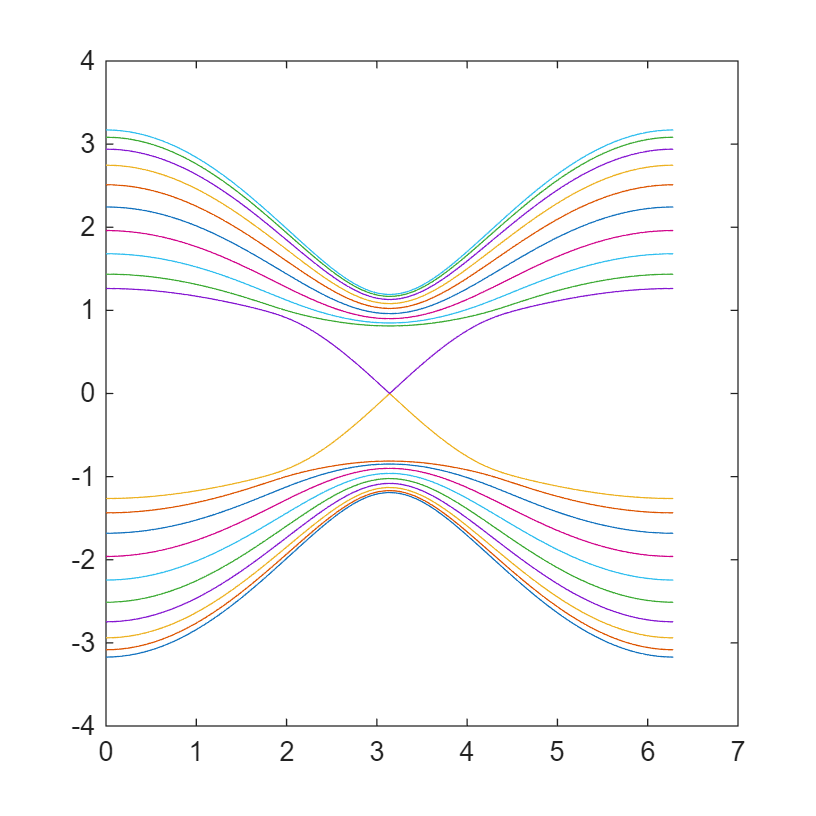

clear;

Central.N_spin = 2;
Central.epsilon = 0;
% Hopping
Central.t = 1;
Central.lambda = 1.2 * Central.t;
Central.v_Fermi = 1;
Central.N_UnitCell = 2;
eta = 1e-4;
% Accuracy = 1e-10;
% 宽度
% Central.N_row = 10;
Central.N_row = [16, 32];
% 长度
Central.N_col = 1000;
% 总格点数
N_tot_site = Central.N_row * Central.N_col * Central.N_UnitCell;
N_Cells = Central.N_row * Central.N_col;
BoundaryCond = "OBC";


Disorder = Central.t * linspace(2.5,3.5,5);
% Disorder = 10;
Fermienergy = 0;
% Fermienergy = sqrt(2);
% 重新归一化以避免指数级小精度 注意取整除长度
% Iteration_Re = 10;

% warning('off')

Band_row = 10;
[H_00, H_01] = Hamiltonian_QAH_2D(Central.lambda, Central.t, Central.v_Fermi, Band_row, BoundaryCond);

kx = [0, 2*pi];
kx_steps = 501;
kx_list = linspace(kx(1), kx(2), kx_steps);
Energy_band = zeros(Central.N_UnitCell*Band_row, kx_steps);
for ii = 1:length(kx_list)
    H = H_00 + exp(1i * kx_list(ii))*H_01 + exp(-1i * kx_list(ii))*H_01';
    Energy_band(:, ii) = eig(H);
end

plot(kx_list, Energy_band)



% 初始透射率应当为1，故取对数后为0
temp_logtrans = 0;
Localization_length = zeros(length(Central.N_row), length(Disorder));
sigma_x = [0,1;1,0];
sigma_y = [0,-1i;1i,0];

ave = 2;

loc_length = zeros(length(Fermienergy), length(Central.N_row));
temp_length = zeros(ave, 1);




for ll = 1:length(Central.N_row)
    Width_loop = Central.N_row(ll);
    N_site_pcol = Width_loop * Central.N_UnitCell;
    [H_CC, V_CC] = Hamiltonian_QAH_2D(Central.lambda, Central.t, Central.v_Fermi, Width_loop, BoundaryCond);
    for kk = 1:length(Disorder)
        % Fermi_Energy_loop = Fermi_Energy(kk);
        for jj = 1:ave
            temp_length(jj) = compute_loc_length(Central.N_col, H_CC, V_CC, Fermienergy, Disorder(kk));
        end
        loc_length(kk, ll) = mean(temp_length);
    end
end

定义$\Lambda=\frac{\xi_M}{M}$，作出$\frac{\xi_M}{M}=f\left(\frac{\xi_\infty}{M}\right)$的图并提取$\xi_\infty$

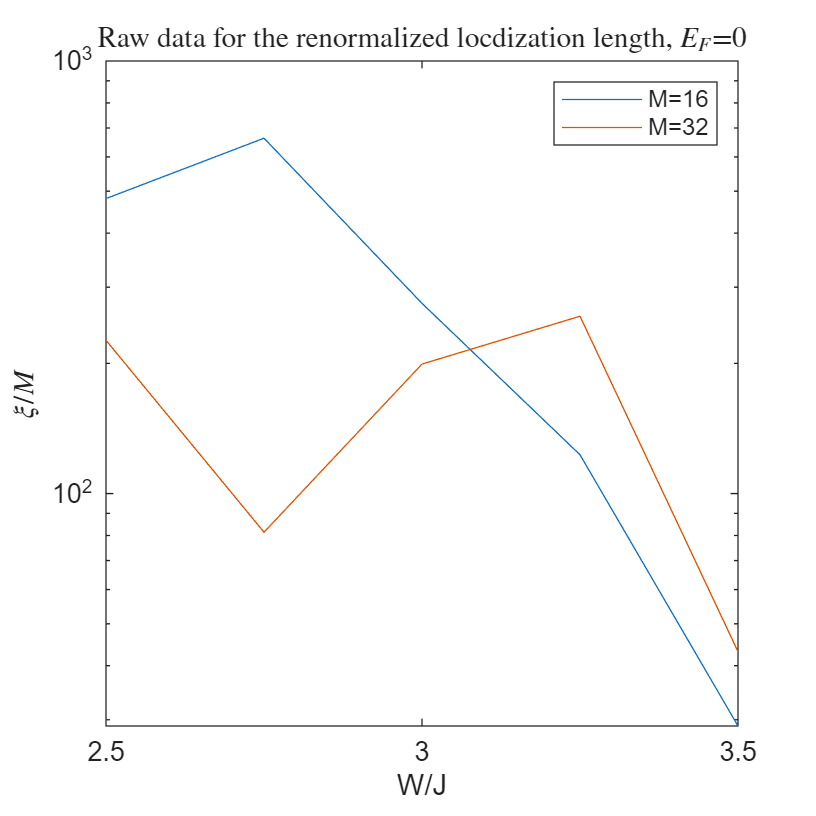


Lambda = loc_length ./ Central.N_row;
% Lambda = Localization_length;
Lambda(Lambda<0) = NaN;

plotlength = (1:Central.N_col);
figure

plot(Disorder, Lambda)
xlabel('W/J')
ylabel('$\xi/M$','Interpreter','latex')
% axis([0.5, max(Central.N_row)+10, 0.1*min(Lambda,[],'all'),10*max(Lambda,[],'all')])
% xscale log
yscale log
legend(strcat('M= ', cellfun(@num2str,num2cell(Central.N_row),'UniformOutput',false)))
% axis([min(Disorder), max(Disorder), 1e-1, max(Localization_length)*10])
title(['Raw data for the renormalized locdization length, $E_F$=',num2str(Fermienergy)],'Interpreter','latex')


toc;

历时 441.806018 秒。





function [loc_length] = compute_loc_length(Length, H_CC, V_CC, Fermi_Energy, Disorder)
r = rank(V_CC);
R_Spectrum = zeros(2*r, Length);
for ii = 1:Length
    if ii > 1
        T = Transfer_Matrix(H_CC, V_CC, Fermi_Energy, Disorder)*Q;
    else
        T = Transfer_Matrix(H_CC, V_CC, Fermi_Energy, Disorder);
    end
    [Q, R] = qr(T);
    [R_diag, ind] = sort(diag(R), 'descend','ComparisonMethod','abs');
    Q = Q(:, ind);
    R_Spectrum(:, ii) = abs(R_diag);
end
lnR = log(R_Spectrum);
Lyapunov_Spectrum = sum(lnR,2)/Length;
loc_length = 1./min(abs(Lyapunov_Spectrum));
end


function [H_CC, V_CC] = Hamiltonian_QAH_2D(lambda, t, v_Fermi, Width, BoundaryCond)

sigma_x = [0,1;1,0];
sigma_y = [0,-1i;1i,0];
sigma_z = [1,0;0,-1];
if BoundaryCond == "PBC"
    H_00 = lambda * kron(eye(Width), sigma_z) + t/2 * kron(circshift(eye(Width),1,2),sigma_z) +t/2 * kron(circshift(eye(Width),-1,2),sigma_z);
    H_00_spin = -1i*v_Fermi/2 * kron(circshift(eye(Width),-1,2),sigma_y) ;
elseif BoundaryCond == "OBC"
    H_00 = lambda * kron(eye(Width), sigma_z) + t/2 * kron(diag(ones(1,Width-1),1),sigma_z) +t/2 * kron(diag(ones(1, Width-1),-1),sigma_z);
    H_00_spin = -1i*v_Fermi/2 * kron(diag(ones(1, Width-1),-1),sigma_y);
end
H_CC = H_00 + H_00_spin + H_00_spin';

V_CC = -1i*v_Fermi/2 * kron(eye(Width), sigma_x)+ t/2 * kron(eye(Width), sigma_z);
end


function T = Transfer_Matrix(H_CC, V_CC, FermiEnergy, Disorder)
eta = 1e-5;
[V, Xi, W] = svd(V_CC);
r = rank(Xi);
V = V(:, 1:r);
W = W(:, 1:r);
Xi = Xi(1:r, 1:r);
H_imp = Disorder * diag(rand(1,size(H_CC,1))-0.5);
G = inv((FermiEnergy + 1i * eta) * eye(size(H_CC,1)) - H_CC - H_imp);
G_vv = (V' * G * V) * Xi;
G_ww = (W' * G * W) * Xi;
G_vw = (W' * G * V) * Xi;
G_wv = (V' * G * W) * Xi;

theta = angle(det(G_vw));


T = [inv(G_vw), -inv(G_vw) * G_ww; 
    G_vv * inv(G_vw), G_wv - G_vv * inv(G_vw) * G_ww];
T = exp(1i * theta / r) * T;
end